# K-Means

clear;clc;
X_train = load('CSE575-HW03-Data.csv');

## Clustering

% Set K for clustering
K = 2;
% Class assignment vector
class_assign = zeros(size(X_train,1),1);
% Previous class assignment vector
prev_class_assign = rand(size(X_train,1),1);

% Set means by choosing K random points from the dataset
means = rand(K,size(X_train,2));
for i=1:K
    r = round(size(X_train,1)*rand(1,1));
    if r==0
        r = r+1;
    end  
    means(i,:) = X_train(r,:);
end

itr = 0;
max_itr = 50;
J_track = [];
% Check if previous and current assignment are same
while sum(prev_class_assign==class_assign)<size(X_train,1)
%     if itr>max_itr
%         break;
%     end
    itr = itr + 1;
    disp(["Iteration " + num2str(itr)]);
    prev_class_assign = class_assign;
    
    % Update class assignments
    for j=1:size(X_train,1)
        dists = zeros(K,1);
        for i=1:K
            dists(i,:) = norm(X_train(j,:)-means(i,:));
        end
        [dist,c] = min(dists);
        class_assign(j,:) = c;
    end

    % Update the means
    means = zeros(K,size(X_train,2));
    for j=1:size(X_train,1)
        for i=1:K
            if class_assign(j,:)==i
                means(i,:) = means(i,:) + X_train(j,:);
            end
        end
    end
    for i=1:K
        means(i,:) = means(i,:)/sum(class_assign==i);
    end

    % Compute cost
    cost = zeros(size(X_train,1),1);
    for j=1:size(X_train,1)
        cost(j) = norm(X_train(j,:)-means(class_assign(j,:),:))^2;
    end
    J = sum(cost);
    disp("Cost J "+num2str(sum(J)));
    % Record cost for plotting
    J_track = [J_track J];
end

Iteration 1


Cost J 19381.9648


Iteration 2


Cost J 18091.1674


Iteration 3


Cost J 17735.1939


Iteration 4


Cost J 17514.441


Iteration 5


Cost J 17479.0347


Iteration 6


Cost J 17479.0347


## Plot

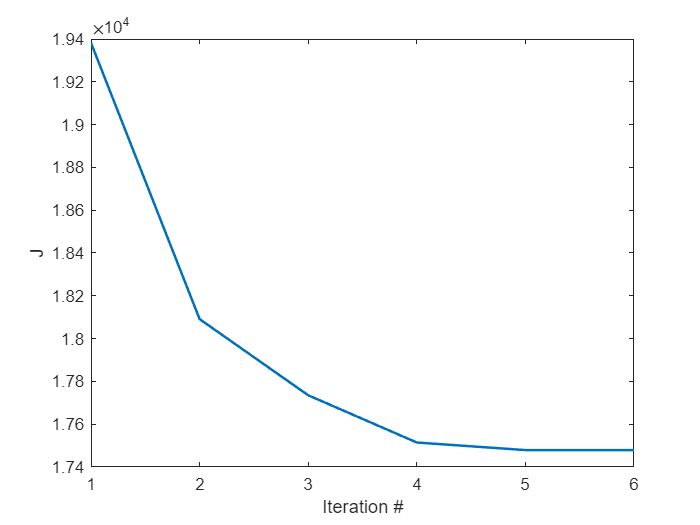

figure;
plot(1:itr, J_track,'LineWidth',1.5)
xlabel('Iteration #')
ylabel('J')

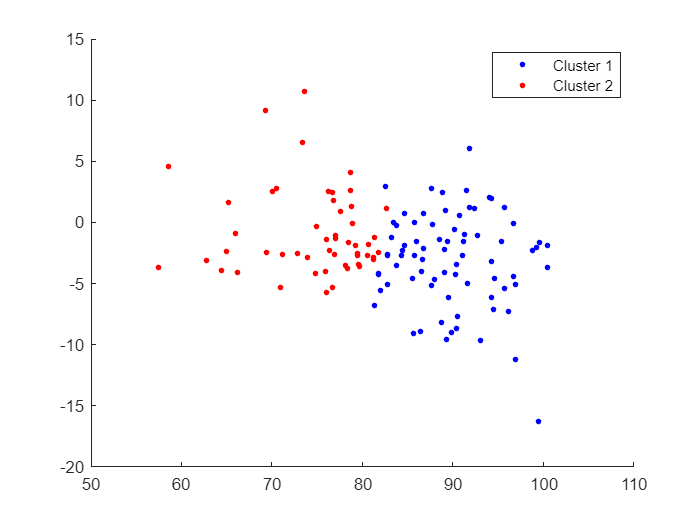

figure;
hold on;
for j=1:size(X_train,1)
    if class_assign(j,:)==1
        plot(X_train(j,1),X_train(j,2),'.','Color','blue','MarkerSize',10)
    else
        plot(X_train(j,1),X_train(j,2),'.','Color','red','MarkerSize',10)
    end
end
legend('Cluster 1', 'Cluster 2')
hold off;